# **Model for Asymmetric Thrust Losses**

### Overview

This script models the effects and power losses from a one-wheel drive car.

To model both a starboard and port driven wheel, it is most simple to just flip the road crowning direction. Remember to change CoGy accordingly.

Only wheel forces are shown in the diagram, drag and gravity forces are neglected.

#### Dependencies:

- `slip2latForce.m`  (function)

- `carV4.m`                  (class)

### Geometry

% Constants
motorOn = true;
slopeDirection = "drive wheel uphill";

car = carV4();
L = car.Wheelbase/1000;
b = car.Trackwidth/1000;
CoGx = car.CoGx;
CoGy = car.CoGy;
Thrust = car.MotorThrust * motorOn;
switch slopeDirection
    case 'flat ground'
        slopeValue = 0;
    case 'drive wheel downhill'
        slopeValue = 1;
    case 'drive wheel uphill'
        slopeValue = -1;
end

% [distX, distY] (t is phi)
dSB = @(t) [(1-CoGx)*L*cos(t) - CoGy*b*sin(t);
    -(CoGy*b*cos(t) + (1-CoGx)*L*sin(t));
    0];

dPB = @(t) [(1-CoGx)*L*cos(t) + (1-CoGy)*b*sin(t);
    (1-CoGy)*b*cos(t) - (1-CoGx)*L*sin(t);
    0];

dPQ = @(t) [-(CoGx*L*cos(t) - (1-CoGy)*b*sin(t));
    (1-CoGy)*b*cos(t) + CoGx*L*sin(t);
    0];

dSQ = @(t) [-(CoGx*L*cos(t) + CoGy*b*sin(t));
    -(CoGy*b*cos(t) - CoGx*L*sin(t));
    0];

% Helper functions to access index of anonymous functions^
getX = @(vec) vec(1);
getY = @(vec) vec(2);
getZ = @(vec) vec(3);

% Governing dynamics equations:
%phi == V(1)
%aR  == V(2)
%aL  == V(3)
QAfun = @(phi) slip2latForce(-phi, car.StaticLoadPQ, car); % V(4)
QRfun = @(aR)  slip2latForce(aR, car.StaticLoadSB, car);  % V(5)
QLfun = @(aL)  slip2latForce(aL, car.StaticLoadPB, car);  % V(6)

sumF = @(t, aR, aL, QA, QR, QL, T)...
    QR*cos(aR) + QL*cos(aL) + 2*QA*cos(t) - T*sin(t) + slopeValue*car.Weight*sin(car.RoadCrown);

findM = @(rVec, Fmag, theta) getZ(cross(rVec, Fmag*[cos(theta); sin(theta); 0])); % theta is clockwise angle from î

sumM = @(t, aR, aL, QA, QR, QL, T, dSB, dPB, dPQ, dSQ)...
    findM(dSB(t), QR, aR+pi/2) + findM(dPB(t), QL, aR+pi/2) + findM(dPQ(t), QA, pi/2-t) + findM(dSQ(t), QA, pi/2-t) + findM(dPQ(t), T, -t);

% Solver setup
SYSTEM = @(V) [
    V(4) - QAfun(V(1));
    V(5) - QRfun(V(2));
    V(6) - QLfun(V(3));
    V(2) - V(3);        % consider wheels parallel at small angle
    sumF(V(1), V(2), V(3), V(4), V(5), V(6), Thrust);
    sumM(V(1), V(2), V(3), V(4), V(5), V(6), Thrust, dSB, dPB, dPQ, dSQ);
    ];
guessVec = [0; 0; 0; Thrust; Thrust; Thrust];
opt = optimoptions('fsolve', ...
    'Display', 'none', ...
    'FunctionTolerance', 1e-6, ...
    'MaxIterations', 1e3, ...
    'MaxFunctionEvaluations', 1e6);

% Solve it!
[solutionVec, fval, exitflag, output] = fsolve(SYSTEM, guessVec, opt);
SolutionCell = num2cell(solutionVec);
[phi, aR, aL, QA, QR, QL] = deal(SolutionCell{:});

frontSlip = rad2deg(aR);
carTilt = rad2deg(phi);
driverSteer = carTilt+frontSlip;

### Energy Modelling

powerDraw = @(Q, slip) abs(Q)*car.NominalSpeed*tan(abs(slip));

PwrA = powerDraw(QA, phi);
PwrR = powerDraw(QR, aR);
PwrL = powerDraw(QL, aL);

powerLoss = 2*PwrA + PwrR + PwrL;

powerPercent = powerLoss/car.NominalMotorPower * 100;

### Output

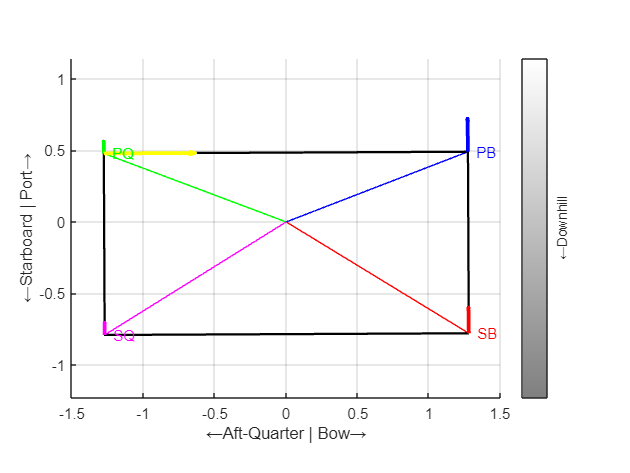

renderit(dSB, dPB, dPQ, dSQ, phi, aR, aL, QA, QR, QL, Thrust, L, slopeValue);

fprintf('Driver steer magnitude:\t\t%5.2f°\nFront wheel slip:\t\t%5.2f°\nRear wheel slip/Chassis tilt:\t%5.2f°', abs(driverSteer), abs(frontSlip), abs(carTilt));

Driver steer magnitude:		 0.46°
Front wheel slip:		 0.72°
Rear wheel slip/Chassis tilt:	 0.27°

fprintf('Power losses @ %i km/h:\n\t%.2f Watts\n\t%.2f%% of motor power ', car.NominalSpeed*3.6, powerLoss, powerPercent);

Power losses @ 40 km/h:
	13.82 Watts
	0.94% of motor power 

### Subfunctions

function renderit(dSB, dPB, dPQ, dSQ, phi, aR, aL, QA, QR, QL, Thrust, L, slope)    % angles in radians

% radii out to wheels
rSB = dSB(phi);
rPB = dPB(phi);
rPQ = dPQ(phi);
rSQ = dSQ(phi);

shorten = L/(4*max(abs([Thrust, QA, QR, QL])));     % scale force vectors

% lateral + motor forces
fSB = shorten*QR*[cos(aR+pi/2); sin(aR+pi/2); 0];
fPB = shorten*QL*[cos(aL+pi/2); sin(aL+pi/2); 0];
fPQ = shorten*QA*[cos(pi/2-phi); sin(pi/2-phi); 0];
fSQ = shorten*QA*[cos(pi/2-phi); sin(pi/2-phi); 0];
tPQ = shorten*Thrust*[cos(-phi); sin(-phi); 0];

figure(1); clf; hold on; grid on; axis equal; axis padded;
xlabel('←Aft-Quarter | Bow→'); ylabel('←Starboard | Port→');

% plot radius vectors from the origin
plot([0, rSB(1)], [0, rSB(2)], 'r-');
plot([0, rPB(1)], [0, rPB(2)], 'b-');
plot([0, rPQ(1)], [0, rPQ(2)], 'g-');
plot([0, rSQ(1)], [0, rSQ(2)], 'm-');

% plot chassis box
X = [rSB(1), rPB(1), rPQ(1), rSQ(1), rSB(1)];
Y = [rSB(2), rPB(2), rPQ(2), rSQ(2), rSB(2)];
plot(X, Y, 'k-', 'LineWidth', 1.5);

% force vectors
quiver(rSB(1), rSB(2), fSB(1), fSB(2), 'off', 'r', 'LineWidth', 2.5);
quiver(rPB(1), rPB(2), fPB(1), fPB(2), 'off', 'b', 'LineWidth', 2.5);
quiver(rPQ(1), rPQ(2), fPQ(1), fPQ(2), 'off', 'g', 'LineWidth', 2.5);
quiver(rSQ(1), rSQ(2), fSQ(1), fSQ(2), 'off', 'm', 'LineWidth', 2.5);
quiver(rPQ(1), rPQ(2), tPQ(1), tPQ(2), 'off', 'y', 'LineWidth', 2.5);

text(rSB(1), rSB(2), '  SB', 'Color', 'r');
text(rPB(1), rPB(2), '  PB', 'Color', 'b');
text(rPQ(1), rPQ(2), '  PQ', 'Color', 'g');
text(rSQ(1), rSQ(2), '  SQ', 'Color', 'm');

if (nargin >= 13 && slope)
    c = colorbar;
    c.Ticks = [];
    lgray = [linspace(0.5, 1, 256)', linspace(0.5, 1, 256)', linspace(0.5, 1, 256)'];

    if (slope == 1)
        colormap(flipud(lgray));
        c.Label.String = 'Downhill→';
    elseif (slope == -1)
        colormap(lgray);
        c.Label.String = '←Downhill';
    else
        error('slope must be -1, 0, 1');
    end
end
end

### General Comments

#### Current Assumptions:

- Drag acts at CoG in -î and does not create a yaw moment

- CoG does not shift when car is on a slope

- Neglects tire hysteresis losses in energy loss calculations

- Assumes static tire loads as defined in `carV4.m`

- ^ Reality is that aerodynamic drag will alter the weight balance

- Front steering is assumed to be parallel, thus both wheels slip equally